# Leading and Trailing Windows

Instructions are in the task pane to the left. Complete and submit each task one at a time. This code sets up the activity.

x = 0:0.2:6

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000


y = sin(x)

y =          0    0.1987    0.3894    0.5646    0.7174    0.8415    0.9320    0.9854    0.9996    0.9738    0.9093    0.8085    0.6755    0.5155    0.3350    0.1411   -0.0584   -0.2555   -0.4425   -0.6119   -0.7568   -0.8716   -0.9516   -0.9937   -0.9962   -0.9589   -0.8835   -0.7728   -0.6313   -0.4646   -0.2794


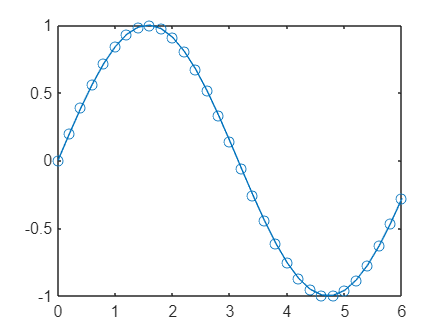

plot(x,y,"o-")

## Task 1

For moving window operations with a noncentered window, use a vector `[``kb` `kf``]` to specify the number of backward and forward points to include. `kb` is the number of trailing (backward) points, and `kf` is the number of leading (forward) points.

For example, the following command calculates the moving average using the current point, 5 trailing points, and 2 leading points.

`dN` `=` `smoothdata``(``d``,``method``,``[``5` `2``])`

**TASK1**

Use the `"movmedian"` method to create a vector named `trail4med` that contains the trailing 4-point median of `y` (i.e., the median of the current point and the three previous points).

**Hint1**

Use the `smoothdata` function, specifying a window with 3 points backward and 0 points forward of the current point. To get the median of the window, use the `"movmedian"` method.

trail4med = smoothdata(y,"movmedian",[3,0])

trail4med =          0    0.0993    0.1987    0.2940    0.4770    0.6410    0.7794    0.8868    0.9587    0.9796    0.9796    0.9416    0.8589    0.7420    0.5955    0.4252    0.2381    0.0414   -0.1570   -0.3490   -0.5272   -0.6843   -0.8142   -0.9116   -0.9726   -0.9763   -0.9763   -0.9212   -0.8281   -0.7020   -0.5479


## Task 2

**TASK2**

Add a plot of `trail4med` as a function of `x` with point markers and a solid line.

**Hint2**

Use `hold` `on` and `hold` `off` to add the smoothed data to the plot. Use the `".-"` line specification with the `plot` function.

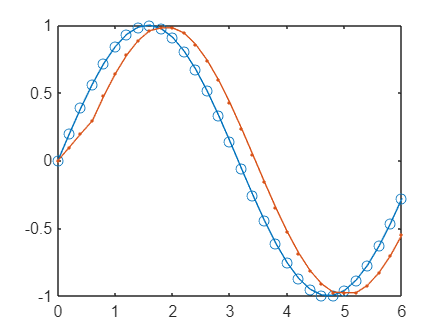

hold on
plot(x,trail4med,".-")
hold off

## Task 3

**TASK3**

Create a vector named `lead4med` that contains the leading 4-point median of `y` (i.e., the median of the current point and the three next points).

**Hint3**

Use the `smoothdata` function, specifying the `movmedian` a window with 0 points backward and 3 points forward of the current point.

`dataM` `=` `smoothdata``(``data``,``"movmedian"``,``[``kb` `kf``])``;`

lead4med = smoothdata(y,"movmedian",[0,3])

lead4med =     0.2940    0.4770    0.6410    0.7794    0.8868    0.9587    0.9796    0.9796    0.9416    0.8589    0.7420    0.5955    0.4252    0.2381    0.0414   -0.1570   -0.3490   -0.5272   -0.6843   -0.8142   -0.9116   -0.9726   -0.9763   -0.9763   -0.9212   -0.8281   -0.7020   -0.5479   -0.4646   -0.3720   -0.2794


## Task 4

**TASK4**

Add a plot of `lead4med` as a function of `x` with point markers and a solid line to the graph.

**Hint4**

Use `hold` `on` and `hold` `off` to add the smoothed data to the plot. Use the `".-"` line specification with the `plot` function.

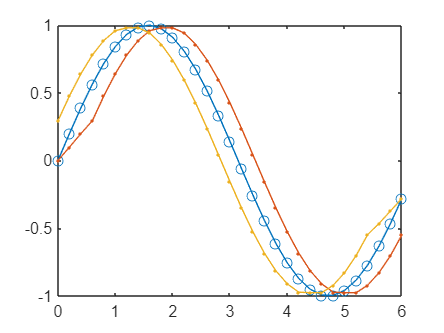

hold on
plot(x,lead4med,".-")
hold off